model = load('model2.mat');

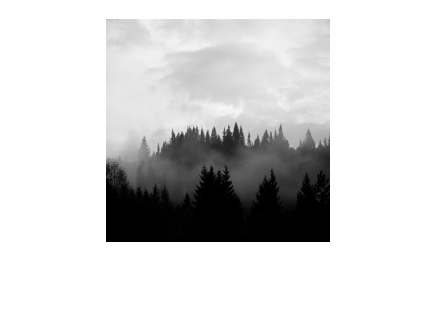

image_path = 'fire_dataset/non_fire_images/non_fire.1.png';
img = imread(image_path);
targetSize = [224, 224, 3];
% Resize the image to the target size
img = imresize(img, targetSize(1:2));
% Ensure the image has 3 color channels (e.g., convert grayscale to RGB)
if size(img, 3) == 1
    img = cat(3, img, img, img); % Convert to RGB
end
imshow(img)

label = classify(model.temp, img);

disp(label)

     non_fire_images 

